# A Estimation curve VS different S_EI:L6 added

## first, setup connctivity map

CurrentFolder = pwd

CurrentFolder = '/home/lai-sang/Documents/GitHub/NYU-Vision-2Drive'

FigurePath = [CurrentFolder '/Figures'];
addpath(CurrentFolder)
addpath([CurrentFolder '/Utils'])
addpath([CurrentFolder '/Data'])

load('NtWk_Archit.mat')

## Variables and Parameters

fixed parameters

p_EEFail = 0.2; S_amb = 0.01;
rE_amb = 0.500; rI_amb = 0.500;

tau_ampa_R = 0.5; tau_ampa_D = 3;
tau_nmda_R = 2; tau_nmda_D = 80;
tau_gaba_R = 0.5; tau_gaba_D = 5;
tau_ref = 2; % time unit is ms

gL_E = 1/20;  Ve = 14/3; rhoE_ampa = 0.8; rhoE_nmda = 0.2;
gL_I = 1/15;  Vi = -2/3; rhoI_ampa = 0.67;rhoI_nmda = 0.33;

NW Connectivity and L6 Input

S_EE = 0.024; S_EI = S_EE*1.5;  
S_II = 0.120; S_IE = S_II*0.153;
% L6 input
S_EL6 = 1/3*S_EE; S_IL6 = 1/3*S_IE;
rE_L6 = 0.25;     rI_L6 = rE_L6*3; %250hz for now

Make up LGN

S_Elgn = 2*S_EE;
S_Ilgn = 2*S_Elgn;
lambda_E = 0.08; % ~16 LGN spike can excite a E neurons. 0.25 spike/ms makes 64 ms for such period. 
lambda_I = 0.08; 

## Network Simulation

S_EE = 0.024, S_EI = 0.036, S_IE = 0.01836, S_II = 0.12
S_Elgn = 0.048, lambda_E = 0.08, S_Ilgn = 0.096, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.5, rI_amb = 0.5

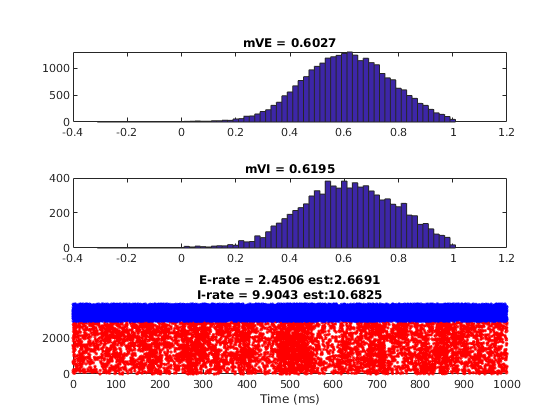

S_EE = 0.024, S_EI = 0.036, S_IE = 0.01836, S_II = 0.12
S_Elgn = 0.048, lambda_E = 0.08, S_Ilgn = 0.096, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.5, rI_amb = 0.5

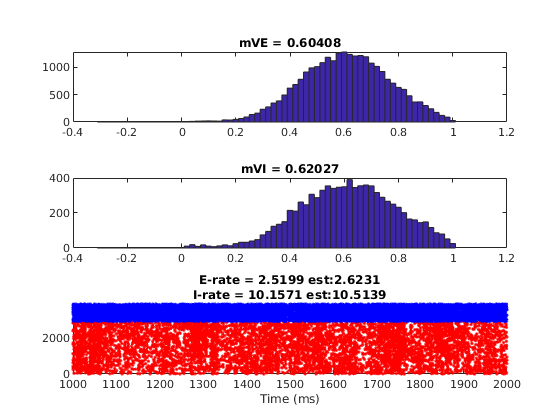

S_EE = 0.024, S_EI = 0.036, S_IE = 0.01836, S_II = 0.12
S_Elgn = 0.048, lambda_E = 0.08, S_Ilgn = 0.096, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.5, rI_amb = 0.5

%% Network Simulation
T = 3000; SimulationT = 1000; dt = 0.1;
% E-to-E delay time
T_EEDly = 0.3; N_EEDly = floor(T_EEDly/dt);
% Setup Results Recording
Fr_NW_BG      = zeros(2,1);
mV_NW_BG      = zeros(2,1);
%Fr_OneStep = zeros(2,EITestN,length(S_IEtest)); % one step MF estimation using network mV

% Compute Neuron Ind
E_sideInd = floor(1*n_E_HC+1):2*n_E_HC;
[E_Ind_X,E_Ind_Y] = meshgrid(E_sideInd,E_sideInd);
E_Ind = (reshape(E_Ind_X,size(E_Ind_X,1)*size(E_Ind_X,2),1)-1)*n_E_HC*N_HC + reshape(E_Ind_Y,size(E_Ind_X,1)*size(E_Ind_X,2),1);

I_sideInd = floor(1*n_I_HC+1):2*n_I_HC;
[I_Ind_X,I_Ind_Y] = meshgrid(I_sideInd,I_sideInd);
I_Ind = (reshape(I_Ind_X,size(I_Ind_X,1)*size(I_Ind_X,2),1)-1)*n_I_HC*N_HC + reshape(I_Ind_Y,size(I_Ind_X,1)*size(I_Ind_X,2),1);

N_EE = mean(sum(C_EE(E_Ind,:),2)); N_EI = mean(sum(C_EI(E_Ind,:),2));
N_IE = mean(sum(C_IE(I_Ind,:),2)); N_II = mean(sum(C_II(I_Ind,:),2));

% Create sliding windows
sampleT = 20;
Sliding = 5;
NSlide = floor(sampleT/Sliding);
TWinBounds = 0:Sliding:T;
Wins = [];
Wins(:,1) = TWinBounds(1:end-NSlide);
Wins(:,2) = TWinBounds(NSlide+1:end);

% The initial states
InSs = load('Initials_L6.mat');
RefTimeE = InSs.RefTimeE; VE = InSs.VE; SpE = InSs.SpE; GE_ampa_R = InSs.GE_ampa_R; GE_nmda_R = InSs.GE_nmda_R; GE_gaba_R = InSs.GE_gaba_R;
GE_ampa_D = InSs.GE_ampa_D; GE_nmda_D = InSs.GE_nmda_D; GE_gaba_D = InSs.GE_gaba_D;
RefTimeI = InSs.RefTimeI; VI = InSs.VI; SpI = InSs.SpI; GI_ampa_R = InSs.GI_ampa_R; GI_nmda_R = InSs.GI_nmda_R; GI_gaba_R = InSs.GI_gaba_R;
GI_ampa_D = InSs.GI_ampa_D; GI_nmda_D = InSs.GI_nmda_D; GI_gaba_D = InSs.GI_gaba_D;
EEDlyRcd = sparse(N_E,N_EEDly);

%E_SpHis= []; I_SpHis=[];
E_Sp = []; I_Sp = [];
VE_T = []; VI_T = [];
sampleN = floor(Sliding/dt); % sample each 2 ms
SimulationN = floor(SimulationT/dt); % show and check every 200ms

BlowUp = false;
SampleInd = 1;

% Trace 1. Fr; 2. mV; 3. V distb
NWTrace = struct('FrEs',   zeros(size(Wins(:,1))), 'FrIs',   zeros(size(Wins(:,1))),...
    'mVEs',   zeros(size(Wins(:,1))), 'mVIs',   zeros(size(Wins(:,1))));
NWTrace.VEDist =  cell(size(Wins(:,1)));
NWTrace.VIDist =  cell(size(Wins(:,1)));
NWTrace.Wins = Wins;

tic
for TimeN = 1:floor(T/dt)
    [oRefTimeE,oVE,oSpE,oGE_ampa_R,oGE_nmda_R,oGE_gaba_R,... % Output
        oGE_ampa_D,oGE_nmda_D,oGE_gaba_D,...
        oRefTimeI,oVI,oSpI,oGI_ampa_R,oGI_nmda_R,oGI_gaba_R,...
        oGI_ampa_D,oGI_nmda_D,oGI_gaba_D,...
        oEEDlyRcd] = ... % A updated N*T Mat recoding the time of kicks taking effect
        V1NetworkUpdate_Ver2_EEDelay(RefTimeE,VE,SpE,GE_ampa_R,GE_nmda_R,GE_gaba_R,... % These are input kept updating
        GE_ampa_D,GE_nmda_D,GE_gaba_D,...
        RefTimeI,VI,SpI,GI_ampa_R,GI_nmda_R,GI_gaba_R,...
        GI_ampa_D,GI_nmda_D,GI_gaba_D,...
        EEDlyRcd,... % A N*T Mat recoding the time of kicks taking effect
        C_EE,C_EI,C_IE,C_II,...
        S_EE,S_EI,S_IE,S_II,...
        tau_ampa_R,tau_ampa_D,tau_nmda_R,tau_nmda_D,tau_gaba_R,tau_gaba_D,tau_ref,... % time unit is ms
        dt,p_EEFail,...
        gL_E,Ve,S_Elgn,rhoE_ampa,rhoE_nmda,...
        gL_I,Vi,S_Ilgn,rhoI_ampa,rhoI_nmda,...
        S_amb,lambda_E,lambda_I,rE_amb,rI_amb,...
        S_EL6,S_IL6,rE_L6,rI_L6); % L6 Parameters          % The lower/upper bounds for kick waiting time
    % iteration
    RefTimeE = oRefTimeE; VE = oVE;SpE = oSpE;GE_ampa_R = oGE_ampa_R; GE_nmda_R = oGE_nmda_R; GE_gaba_R = oGE_gaba_R;
    GE_ampa_D = oGE_ampa_D; GE_nmda_D = oGE_nmda_D; GE_gaba_D = oGE_gaba_D;
    RefTimeI = oRefTimeI; VI = oVI;SpI = oSpI;GI_ampa_R = oGI_ampa_R; GI_nmda_R = oGI_nmda_R; GI_gaba_R = oGI_gaba_R;
    GI_ampa_D = oGI_ampa_D; GI_nmda_D = oGI_nmda_D; GI_gaba_D = oGI_gaba_D;
    EEDlyRcd = oEEDlyRcd;
    
    % When reaching every 500ms, demostrate and pause
    if mod(TimeN,SimulationN) == 0 && TimeN*dt>=400
        ParameterDisp = ['S_EE = ' num2str(S_EE) ', S_EI = ' num2str(S_EI) ...
            ', S_IE = ' num2str(S_IE) ', S_II = ' num2str(S_II) '\n' ...
            'S_Elgn = ' num2str(S_Elgn) ', lambda_E = ' num2str(lambda_E) ...
            ', S_Ilgn = ' num2str(S_Ilgn) ', lambda_I = ' num2str(lambda_I) '\n' ...
            'S_amb = ' num2str(S_amb) ', rE_amb = ' num2str(rE_amb) ', rI_amb = ' num2str(rI_amb)];
        
        fprintf(ParameterDisp)
        h = figure('Name','TestRaster');
        subplot 311
        hist(oVE,-0.3:0.02:1)
        title(['mVE = ' num2str(nanmean(VE_T))])
        %E_SpHis = [E_SpHis,sum(oSpE)];
        %axis([-0.4 1.1 0 6000])
        
        subplot 312
        hist(oVI,-0.3:0.02:1)
        title(['mVI = ' num2str(nanmean(VI_T))])
              
        %E_Ind = 10000:13000; I_Ind = 3300:4300;
        scatterE = find(ismember(E_Sp(:,1),E_Ind));
        scatterI = find(ismember(I_Sp(:,1),I_Ind));
        [~,E_Fire_Ind] = ismember(E_Sp(scatterE,1),E_Ind);
        [~,I_Fire_Ind] = ismember(I_Sp(scatterI,1),I_Ind);
        
        WinSize = SimulationT;
        T_RateWindow = [TimeN*dt-WinSize TimeN*dt];
        E_SpInd = find(E_Sp(:,2)>=T_RateWindow(1) & E_Sp(:,2)<=T_RateWindow(2) & ismember(E_Sp(:,1),E_Ind));
        I_SpInd = find(I_Sp(:,2)>=T_RateWindow(1) & I_Sp(:,2)<=T_RateWindow(2) & ismember(I_Sp(:,1),I_Ind));
        E_Rate = length(E_SpInd)/(WinSize/1000)/length(E_Ind);
        I_Rate = length(I_SpInd)/(WinSize/1000)/length(I_Ind);
        
        f_EnIOneStep = MeanFieldEst_BkGd_L6_OneStep(N_EE,N_EI,N_IE,N_II,...
                                                    S_EE,S_EI,S_IE,S_II,p_EEFail,...
                                                    lambda_E,S_Elgn,rE_amb,S_amb,...
                                                    lambda_I,S_Ilgn,rI_amb,...
                                                    S_EL6,S_IL6,rE_L6,rI_L6,...
                                                    gL_E,gL_I,Ve,Vi,nanmean(VE_T),nanmean(VI_T));
        %
        subplot 313
        hold on
        scatter(E_Sp(scatterE,2),E_Fire_Ind,'r.')
        scatter(I_Sp(scatterI,2),I_Fire_Ind+max(E_Fire_Ind),'b.');
        title({['E-rate = ' num2str(E_Rate) ' est:' num2str(f_EnIOneStep(1))],['I-rate = ' num2str(I_Rate) ' est:' num2str(f_EnIOneStep(2))]})
        xlabel('Time (ms)')
        xlim(T_RateWindow)
        ylim([0 max(I_Fire_Ind)+max(E_Fire_Ind)])
        drawnow
        %pause
        close(h)
        % end of 500ms plot
    end
    
    % every 20ms time window
    if mod(TimeN,sampleN) == 0 && TimeN >= floor(sampleT/dt)
        WinSize = NWTrace.Wins(SampleInd,2) - NWTrace.Wins(SampleInd,1);
        T_RateWindow = NWTrace.Wins(SampleInd,:);
        E_SpInd = find(E_Sp(:,2)>=T_RateWindow(1) & E_Sp(:,2)<=T_RateWindow(2) & ismember(E_Sp(:,1),E_Ind));
        I_SpInd = find(I_Sp(:,2)>=T_RateWindow(1) & I_Sp(:,2)<=T_RateWindow(2) & ismember(I_Sp(:,1),I_Ind));
        
        NWTrace.FrEs(SampleInd) = length(E_SpInd)/(WinSize/1000)/length(E_Ind);
        NWTrace.FrIs(SampleInd) = length(I_SpInd)/(WinSize/1000)/length(I_Ind);
        NWTrace.mVEs(SampleInd) = nanmean(oVE(E_Ind));
        NWTrace.mVIs(SampleInd) = nanmean(oVI(I_Ind));
        
        NWTrace.VEDist{SampleInd} = oVE(E_Ind);
        NWTrace.VIDist{SampleInd} = oVI(I_Ind);
        
        SampleInd = SampleInd + 1;
    end
    
    E_Sp = [E_Sp;[find(oSpE),ones(size(find(oSpE)))*TimeN*dt]];
    I_Sp = [I_Sp;[find(oSpI),ones(size(find(oSpI)))*TimeN*dt]];
    VE_T = [VE_T;nanmean(oVE(E_Ind))];
    VI_T = [VI_T;nanmean(oVI(I_Ind))];
    
    if sum(isnan(oVE))>0.80*N_E
        BlowUp = true;
        disp('warning!: Network exploded')
        break
    end
    
    % the end of iteration
end

toc

Elapsed time is 95.175897 seconds.



NWTrace.E_Sp = E_Sp; NWTrace.I_Sp = I_Sp;


% If blown up, discard other recordings...
if ~BlowUp
    Fr_NW_BG     = [E_Rate;I_Rate];
    mV_NW_BG     = [nanmean(VE_T),nanmean(VI_T)];
    %Fr_OneStep(:,S_EIInd,S_IEInd) = f_EnIOneStep;
end
% end of S_IE loop



## Now, with drive

First figure out orientation domains

ODNum = 4; % 4 orientation domains
% A function from Neuron Ind and spatial scales to Orientation Domains
OD_E = zeros(size(NnE.X));
OD_EMap = zeros(n_E_HC*N_HC);
for NeuInd = 1:length(NnE.X)
OD_E(NeuInd) = OrientDom(ODNum,NnE.X(NeuInd),NnE.Y(NeuInd),n_E_HC);
OD_EMap(NnE.Y(NeuInd),NnE.X(NeuInd)) = OD_E(NeuInd);
end

OD_I = zeros(size(NnI.X));
OD_IMap = zeros(n_I_HC*N_HC);
for NeuInd = 1:length(NnI.X)
OD_I(NeuInd) = OrientDom(ODNum,NnI.X(NeuInd),NnI.Y(NeuInd),n_I_HC);
OD_IMap(NnI.Y(NeuInd),NnI.X(NeuInd)) = OD_I(NeuInd);
end

LGN input classified by domains

DriveE = [60,53,48,53]*4/1e3; % Ordered by domains, times the number of lgn cells, normalized by 1000ms
DriveI = 48*4/1e3;
lambda_E_drive = DriveE(OD_E)';
lambda_I_drive = DriveI;

Simulation

Then make a transfer between neurons in HCs and 10*10 pixels

% PixelNum per HC
NPixX = 2; %10
NPixY = 2;
%% Network Simulation
T = 10000; SimulationT = 5000; dt = 0.2;
% E-to-E delay time
T_EEDly = 0.8; N_EEDly = floor(T_EEDly/dt);
% Setup Results Recording

FrE_NW_Drive = zeros(N_E,1);
FrI_NW_Drive = zeros(N_I,1);
mVE_NW_Drive = zeros(N_E,1);
mVI_NW_Drive = zeros(N_I,1);
%Fr_OneStep = zeros(2,EITestN,length(S_IEtest)); % one step MF estimation using network mV

% Create sliding windows
sampleT = 200;
Sliding = 100;
NSlide = floor(sampleT/Sliding);
TWinBounds = 0:Sliding:T;
Wins = [];
Wins(:,1) = TWinBounds(1:end-NSlide);
Wins(:,2) = TWinBounds(NSlide+1:end);

% The initial states
InSs = load('Initials_L6.mat');
RefTimeE = InSs.RefTimeE; VE = InSs.VE; SpE = InSs.SpE; GE_ampa_R = InSs.GE_ampa_R; GE_nmda_R = InSs.GE_nmda_R; GE_gaba_R = InSs.GE_gaba_R;
GE_ampa_D = InSs.GE_ampa_D; GE_nmda_D = InSs.GE_nmda_D; GE_gaba_D = InSs.GE_gaba_D;
RefTimeI = InSs.RefTimeI; VI = InSs.VI; SpI = InSs.SpI; GI_ampa_R = InSs.GI_ampa_R; GI_nmda_R = InSs.GI_nmda_R; GI_gaba_R = InSs.GI_gaba_R;
GI_ampa_D = InSs.GI_ampa_D; GI_nmda_D = InSs.GI_nmda_D; GI_gaba_D = InSs.GI_gaba_D;
EEDlyRcd = sparse(N_E,N_EEDly);

%E_SpHis= []; I_SpHis=[];
E_Sp = []; I_Sp = [];
VE_T = []; VI_T = [];
sampleN = floor(Sliding/dt); % sample each 2 ms
SimulationN = floor(SimulationT/dt); % show and check every 200ms

BlowUp = false;
SampleInd = 1;

% Trace 1. Fr; 2. mV; 3. V distb
NWTrace = struct('FrEs',   zeros(N_E,size(Wins,1)), 'FrIs',   zeros(N_I,size(Wins,1)),...
                 'mVEs',   zeros(N_E,size(Wins,1)), 'mVIs',   zeros(N_I,size(Wins,1)));
NWTrace.VEDist =  cell(size(Wins(:,1)));
NWTrace.VIDist =  cell(size(Wins(:,1)));
NWTrace.Wins = Wins;

tic
for TimeN = 1:floor(T/dt)
    [oRefTimeE,oVE,oSpE,oGE_ampa_R,oGE_nmda_R,oGE_gaba_R,... % Output
        oGE_ampa_D,oGE_nmda_D,oGE_gaba_D,...
        oRefTimeI,oVI,oSpI,oGI_ampa_R,oGI_nmda_R,oGI_gaba_R,...
        oGI_ampa_D,oGI_nmda_D,oGI_gaba_D,...
        oEEDlyRcd] = ... % A updated N*T Mat recoding the time of kicks taking effect
        V1NetworkUpdate_Ver2_EEDelay(RefTimeE,VE,SpE,GE_ampa_R,GE_nmda_R,GE_gaba_R,... % These are input kept updating
        GE_ampa_D,GE_nmda_D,GE_gaba_D,...
        RefTimeI,VI,SpI,GI_ampa_R,GI_nmda_R,GI_gaba_R,...
        GI_ampa_D,GI_nmda_D,GI_gaba_D,...
        EEDlyRcd,... % A N*T Mat recoding the time of kicks taking effect
        C_EE,C_EI,C_IE,C_II,...
        S_EE,S_EI,S_IE,S_II,...
        tau_ampa_R,tau_ampa_D,tau_nmda_R,tau_nmda_D,tau_gaba_R,tau_gaba_D,tau_ref,... % time unit is ms
        dt,p_EEFail,...
        gL_E,Ve,S_Elgn,rhoE_ampa,rhoE_nmda,...
        gL_I,Vi,S_Ilgn,rhoI_ampa,rhoI_nmda,...
        S_amb,lambda_E_drive,lambda_I_drive,rE_amb,rI_amb,...
        S_EL6,S_IL6,rE_L6,rI_L6); % L6 Parameters          % The lower/upper bounds for kick waiting time
    % iteration
    RefTimeE = oRefTimeE; VE = oVE;SpE = oSpE;GE_ampa_R = oGE_ampa_R; GE_nmda_R = oGE_nmda_R; GE_gaba_R = oGE_gaba_R;
    GE_ampa_D = oGE_ampa_D; GE_nmda_D = oGE_nmda_D; GE_gaba_D = oGE_gaba_D;
    RefTimeI = oRefTimeI; VI = oVI;SpI = oSpI;GI_ampa_R = oGI_ampa_R; GI_nmda_R = oGI_nmda_R; GI_gaba_R = oGI_gaba_R;
    GI_ampa_D = oGI_ampa_D; GI_nmda_D = oGI_nmda_D; GI_gaba_D = oGI_gaba_D;
    EEDlyRcd = oEEDlyRcd;
    
    % When reaching every 500ms, demostrate and pause
    if mod(TimeN,SimulationN) == 0 && TimeN*dt>=400
        ParameterDisp = ['S_EE = ' num2str(S_EE) ', S_EI = ' num2str(S_EI) ...
            ', S_IE = ' num2str(S_IE) ', S_II = ' num2str(S_II) '\n' ...
            'S_Elgn = ' num2str(S_Elgn) ', lambda_E = ' num2str(mean(lambda_E_drive)) ...
            ', S_Ilgn = ' num2str(S_Ilgn) ', lambda_I = ' num2str(lambda_I) '\n' ...
            'S_amb = ' num2str(S_amb) ', rE_amb = ' num2str(rE_amb) ', rI_amb = ' num2str(rI_amb)];
        
        fprintf(ParameterDisp)
        WinSize = SimulationT;
        Window = [TimeN*dt-WinSize TimeN*dt];
        
        h = figure('Name','Field_f&V');
        
        subplot 231
        ESPinWin = E_Sp(:,2)>=Window(1) & E_Sp(:,2)<=Window(2);
        E_SpGood = E_Sp(ESPinWin,1);
        [SpCN, SpCI] = groupcounts(E_SpGood);
        FrE_temp = zeros(N_E,1);
        FrE_temp(SpCI) = SpCN*1e3/SimulationT;
        FrE_Map = reshape(FrE_temp,N_HC*n_E_HC,N_HC*n_E_HC); % not used here
        
        [FrEPixMat,NnEPixel] = NeuVec2Pixel(FrE_temp,NnE,NPixX*N_HC,NPixY*N_HC);
        imagesc(FrEPixMat); title('FrE')
        set(gca,'YDir','normal')
        axis square
        colormap jet
        colorbar
        
        subplot 234
        ISPinWin = (I_Sp(:,2)>=Window(1) & I_Sp(:,2)<=Window(2));
        I_SpGood = I_Sp(ISPinWin,1);
        [SpCN, SpCI] = groupcounts(I_SpGood);
        FrI_temp = zeros(N_I,1);
        FrI_temp(SpCI) = SpCN*1e3/SimulationT;
        FrI_Map = reshape(FrI_temp,N_HC*n_I_HC,N_HC*n_I_HC);
        
        [FrIPixMat,NnIPixel] = NeuVec2Pixel(FrI_temp,NnI,NPixX*N_HC,NPixY*N_HC);
        imagesc(FrIPixMat); title('FrI')
        set(gca,'YDir','normal')
        axis square
        colormap jet
        colorbar
        
        SmallWinRange = NWTrace.Wins(:,1)>=Window(1) & NWTrace.Wins(:,2)<=Window(2);
        subplot 232
        mVE_temp = nanmean(NWTrace.mVEs(:,SmallWinRange),2);
        mVE_Map = reshape(mVE_temp,N_HC*n_E_HC,N_HC*n_E_HC);
        
        [mVEPixMat,~] = NeuVec2Pixel(mVE_temp,NnE,NPixX*N_HC,NPixY*N_HC);
        imagesc(mVEPixMat); title('mVE')
        set(gca,'YDir','normal')
        axis square
        colormap jet
        colorbar
        
        subplot 235
        mVI_temp = nanmean(NWTrace.mVIs(:,SmallWinRange),2);
        mVI_Map = reshape(mVI_temp,N_HC*n_I_HC,N_HC*n_I_HC);
        
        [mVIPixMat,~] = NeuVec2Pixel(mVI_temp,NnI,NPixX*N_HC,NPixY*N_HC);
        imagesc(mVIPixMat); title('mVI')
        set(gca,'YDir','normal')
        axis square
        colormap jet
        colorbar
        
        subplot 233
        imagesc(OD_EMap);axis square
        set(gca,'YDir','normal')
        
        subplot 236
        imagesc(OD_IMap);axis square
        set(gca,'YDir','normal')
        
        drawnow
        %pause
        close(h)
        toc
        % end of 500ms plot
    end
    
    % every 20ms time window
    if mod(TimeN,sampleN) == 0 && TimeN >= floor(sampleT/dt)
        WinSize = NWTrace.Wins(SampleInd,2) - NWTrace.Wins(SampleInd,1);
        T_RateWindow = NWTrace.Wins(SampleInd,:);
        
        ESpInWinSm = E_Sp(:,2)>=T_RateWindow(1) & E_Sp(:,2)<=T_RateWindow(2) ;
        ESpGoodSm = E_Sp(ESpInWinSm,1);
        [SpCN, SpCI] = groupcounts(ESpGoodSm);
        NWTrace.FrEs(SpCI,SampleInd) = SpCN*1e3/WinSize;
        
        ISpInWinSm = I_Sp(:,2)>=T_RateWindow(1) & I_Sp(:,2)<=T_RateWindow(2) ;
        ISpGoodSm = I_Sp(ISpInWinSm,1);
        [SpCN, SpCI] = groupcounts(ISpGoodSm);
        NWTrace.FrIs(SpCI,SampleInd) = SpCN*1e3/WinSize;
        
        NWTrace.mVEs(:,SampleInd) = oVE;
        NWTrace.mVIs(:,SampleInd) = oVI;
              
        SampleInd = SampleInd + 1
        sum(isnan(oVE))/N_E
    end
    
    E_Sp = [E_Sp;[find(oSpE),ones(size(find(oSpE)))*TimeN*dt]];
    I_Sp = [I_Sp;[find(oSpI),ones(size(find(oSpI)))*TimeN*dt]];
    
%     if sum(isnan(oVE))>0.80*N_E
%         BlowUp = true;
%         disp('warning!: Network exploded')
%         break
%     end
    
    % the end of iteration
end

SampleInd = 2

ans = 0.0467

SampleInd = 3

ans = 0.0213

SampleInd = 4

ans = 0.0292

SampleInd = 5

ans = 0.0406

SampleInd = 6

ans = 0.0221

SampleInd = 7

ans = 0.0290

SampleInd = 8

ans = 0.0388

SampleInd = 9

ans = 0.0246

SampleInd = 10

ans = 0.0291

SampleInd = 11

ans = 0.0423

SampleInd = 12

ans = 0.0326

SampleInd = 13

ans = 0.0217

SampleInd = 14

ans = 0.0411

SampleInd = 15

ans = 0.0258

SampleInd = 16

ans = 0.0316

SampleInd = 17

ans = 0.0368

SampleInd = 18

ans = 0.0270

SampleInd = 19

ans = 0.0322

SampleInd = 20

ans = 0.0362

SampleInd = 21

ans = 0.0322

SampleInd = 22

ans = 0.0246

SampleInd = 23

ans = 0.0271

SampleInd = 24

ans = 0.0440

SampleInd = 25

ans = 0.0293

SampleInd = 26

ans = 0.0272

SampleInd = 27

ans = 0.0424

SampleInd = 28

ans = 0.0296

SampleInd = 29

ans = 0.0243

SampleInd = 30

ans = 0.0366

SampleInd = 31

ans = 0.0291

SampleInd = 32

ans = 0.0269

SampleInd = 33

ans = 0.0407

SampleInd = 34

ans = 0.0255

SampleInd = 35

ans = 0.0313

SampleInd = 36

ans = 0.0407

SampleInd = 37

ans = 0.0206

SampleInd = 38

ans = 0.0392

SampleInd = 39

ans = 0.0319

SampleInd = 40

ans = 0.0255

SampleInd = 41

ans = 0.0391

SampleInd = 42

ans = 0.0320

SampleInd = 43

ans = 0.0274

SampleInd = 44

ans = 0.0298

SampleInd = 45

ans = 0.0367

SampleInd = 46

ans = 0.0243

SampleInd = 47

ans = 0.0333

SampleInd = 48

ans = 0.0378

SampleInd = 49

ans = 0.0257

S_EE = 0.024, S_EI = 0.036, S_IE = 0.01836, S_II = 0.12
S_Elgn = 0.048, lambda_E = 0.21415, S_Ilgn = 0.096, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.5, rI_amb = 0.5

Elapsed time is 284.887927 seconds.


SampleInd = 50

ans = 0.0309

SampleInd = 51

ans = 0.0337

SampleInd = 52

ans = 0.0282

SampleInd = 53

ans = 0.0366

SampleInd = 54

ans = 0.0336

SampleInd = 55

ans = 0.0229

SampleInd = 56

ans = 0.0372

SampleInd = 57

ans = 0.0333

SampleInd = 58

ans = 0.0225

SampleInd = 59

ans = 0.0317

SampleInd = 60

ans = 0.0359

SampleInd = 61

ans = 0.0231

SampleInd = 62

ans = 0.0380

SampleInd = 63

ans = 0.0327

SampleInd = 64

ans = 0.0198

SampleInd = 65

ans = 0.0409

SampleInd = 66

ans = 0.0303

SampleInd = 67

ans = 0.0238

SampleInd = 68

ans = 0.0307

SampleInd = 69

ans = 0.0292

SampleInd = 70

ans = 0.0340

SampleInd = 71

ans = 0.0241

SampleInd = 72

ans = 0.0376

SampleInd = 73

ans = 0.0312

SampleInd = 74

ans = 0.0327

SampleInd = 75

ans = 0.0267

SampleInd = 76

ans = 0.0318

SampleInd = 77

ans = 0.0340

SampleInd = 78

ans = 0.0286

SampleInd = 79

ans = 0.0360

SampleInd = 80

ans = 0.0364

SampleInd = 81

ans = 0.0224

SampleInd = 82

ans = 0.0319

SampleInd = 83

ans = 0.0376

SampleInd = 84

ans = 0.0290

SampleInd = 85

ans = 0.0251

SampleInd = 86

ans = 0.0370

SampleInd = 87

ans = 0.0332

SampleInd = 88

ans = 0.0333

SampleInd = 89

ans = 0.0269

SampleInd = 90

ans = 0.0354

SampleInd = 91

ans = 0.0279

SampleInd = 92

ans = 0.0250

SampleInd = 93

ans = 0.0383

SampleInd = 94

ans = 0.0314

SampleInd = 95

ans = 0.0299

SampleInd = 96

ans = 0.0391

SampleInd = 97

ans = 0.0324

SampleInd = 98

ans = 0.0249

SampleInd = 99

ans = 0.0277

S_EE = 0.024, S_EI = 0.036, S_IE = 0.01836, S_II = 0.12
S_Elgn = 0.048, lambda_E = 0.21415, S_Ilgn = 0.096, lambda_I = 0.08
S_amb = 0.01, rE_amb = 0.5, rI_amb = 0.5

Elapsed time is 933.644671 seconds.


SampleInd = 100

ans = 0.0375

toc

Elapsed time is 933.739271 seconds.



NWTrace.E_Sp = E_Sp; NWTrace.I_Sp = I_Sp;

## MF linear equation for pixels: 1 Matrices

FrEPixVec = reshape(FrEPixMat,NPixX*N_HC*NPixY*N_HC,1);
FrIPixVec = reshape(FrIPixMat,NPixX*N_HC*NPixY*N_HC,1);
mVEPixVec = reshape(mVEPixMat,NPixX*N_HC*NPixY*N_HC,1);
mVIPixVec = reshape(mVIPixMat,NPixX*N_HC*NPixY*N_HC,1);
% First, get connectivity matrix between Pixels
C_EE_Pixel = zeros(length(FrEPixVec));
C_EI_Pixel = zeros(length(FrEPixVec));
C_IE_Pixel = zeros(length(FrEPixVec));
C_II_Pixel = zeros(length(FrEPixVec));
tic
AA = length(FrEPixVec);
parfor PixIndPost = 1:AA
    for PixIndPre = 1:AA
        C_EE_Pixel(PixIndPost,PixIndPre) = mean(sum(C_EE(NnEPixel.Vec == PixIndPost, NnEPixel.Vec == PixIndPre),2));
        C_EI_Pixel(PixIndPost,PixIndPre) = mean(sum(C_EI(NnEPixel.Vec == PixIndPost, NnIPixel.Vec == PixIndPre),2));
        C_IE_Pixel(PixIndPost,PixIndPre) = mean(sum(C_IE(NnIPixel.Vec == PixIndPost, NnEPixel.Vec == PixIndPre),2));
        C_II_Pixel(PixIndPost,PixIndPre) = mean(sum(C_II(NnIPixel.Vec == PixIndPost, NnIPixel.Vec == PixIndPre),2));
    end    
end
toc

Elapsed time is 2.043683 seconds.


C_EE_Pixel_Us = sparse(C_EE_Pixel);
C_IE_Pixel_Us = sparse(C_IE_Pixel);
C_EI_Pixel_Us = sparse(C_EI_Pixel);
C_II_Pixel_Us = sparse(C_II_Pixel);

MF linear equation for pixels: 2 MF Eqns

% Mats
MatEE = (S_EE*(1-p_EEFail))*C_EE_Pixel_Us.*(Ve-repmat(mVEPixVec,1,NPixX*N_HC*NPixY*N_HC)); % Need Ref here??
MatEI = S_EI *              C_EI_Pixel_Us.*(Vi-repmat(mVEPixVec,1,NPixX*N_HC*NPixY*N_HC));
MatIE = S_IE *              C_IE_Pixel_Us.*(Ve-repmat(mVIPixVec,1,NPixX*N_HC*NPixY*N_HC));
MatII = S_II *              C_II_Pixel_Us.*(Vi-repmat(mVIPixVec,1,NPixX*N_HC*NPixY*N_HC));
ConnMat = [MatEE,MatEI;MatIE,MatII];
% Leak
LeakE = gL_E * (0-mVEPixVec) * 1e3;
LeakI = gL_I * (0-mVIPixVec) * 1e3;
LeakV = [LeakE;LeakI];
% Ext
lambda_E_Pixel = zeros(size(mVEPixVec));
for PixInd = 1:length(FrEPixVec)
    lambda_E_Pixel(PixInd) = mean(lambda_E_drive(NnEPixel.Vec == PixInd));
end
lambda_I_Pixel = lambda_I_drive;
ExtE = (lambda_E_Pixel*S_Elgn + rE_amb*S_amb + rE_L6*S_EL6).*(Ve-mVEPixVec) * 1e3;
ExtI = (lambda_I_Pixel*S_Ilgn + rI_amb*S_amb + rI_L6*S_IL6) *(Ve-mVIPixVec) * 1e3;
ExtV = [ExtE;ExtI];
% Ref Vec
RefE = 1-FrEPixVec*tau_ref/1e3;
RefI = 1-FrIPixVec*tau_ref/1e3;
RefM = sparse(diag([RefE;RefI]));
% L4 Frs
Fr_L4 = [FrEPixVec;FrIPixVec];

% MF Equations:
Fr_MF = RefM * (ConnMat*Fr_L4 + ExtV + LeakV);
Fr_MFinv = (sparse(eye(2*NPixX*N_HC*NPixY*N_HC))-RefM*ConnMat)^-1 * (RefM * ( ExtV + LeakV));

% Err
FrErr = Fr_MFinv - Fr_L4;

figure('Name','MF and Real Fr')
subplot 231
imagesc(FrEPixMat); title('FrE')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar

subplot 234
imagesc(FrIPixMat); title('FrI')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar

subplot 232
FrEPixMat_MF = reshape(Fr_MFinv(1:length(FrEPixVec)),NPixY*N_HC,NPixX*N_HC)

FrEPixMat_MF =    12.9822   16.3830   15.6515   12.0365   13.2819   15.7863
   12.8783   13.5645   13.4667   12.4555   12.5929   14.3921
   14.1950   15.1504   14.4273   11.2281   13.8080   14.3180
   11.1168   13.4224   14.0613   16.8288   12.4029   14.8922
   12.3381   16.8228   16.3532   13.8975   12.5220   14.5069
   11.9887   15.4272   15.2271   12.2772   11.1111   18.2095


imagesc(FrEPixMat_MF); title('FrE_{MF}')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar

subplot 235
FrIPixMat_MF = reshape(Fr_MFinv(length(FrEPixVec)+1:end),NPixY*N_HC,NPixX*N_HC)

FrIPixMat_MF =    37.8582   44.9040   44.5533   38.4145   39.9823   41.8867
   40.2945   46.5567   44.5501   40.3856   43.9786   42.4252
   41.9308   45.6218   45.3133   41.3799   42.6850   41.8900
   36.9317   45.1844   47.4775   47.8973   43.8187   41.7391
   39.4462   49.5286   50.1837   45.4449   42.2426   44.4429
   36.1176   44.5622   44.9788   37.2532   37.8944   43.2780


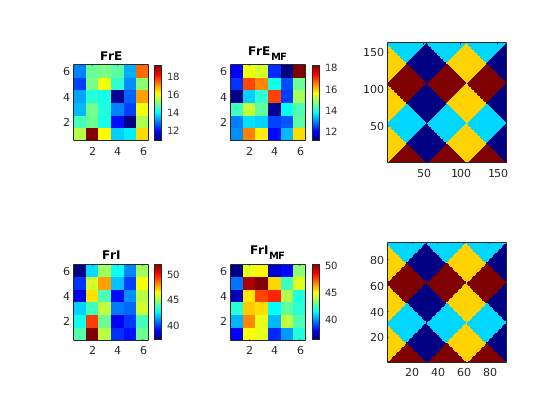

imagesc(FrIPixMat_MF); title('FrI_{MF}')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar

subplot 233
imagesc(OD_EMap);axis square
set(gca,'YDir','normal')

subplot 236
imagesc(OD_IMap);axis square
set(gca,'YDir','normal')

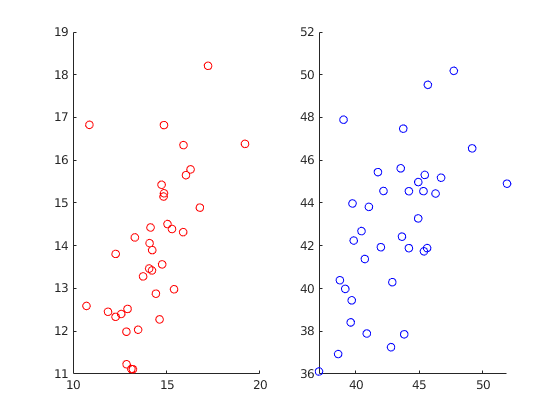


figure('Name','Fr Comparison')
subplot 121
scatter(FrEPixVec,Fr_MFinv(1:NPixX*N_HC*NPixY*N_HC),'ro')

subplot 122
scatter(FrIPixVec,Fr_MFinv(NPixX*N_HC*NPixY*N_HC+1:end),'bo')

Result not very good. On the other hand, should concern real input since we are only averaging from 25/8 neurons?

Check code: Mistakes in row and column?